# RBE 501: Coding Forward Kinematics in Robotics Toolkit

## *Build Denso's HSR robot with Robotics Toolkit*

In the prompt of this assignment, we are given the following table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 205 			& 0	& 220	& \theta_1			\cr
2			& 275 			& 0		& 0	& \theta_2		\cr
3			& 0 			& 0			& d_3 & 0	\cr
4	        & 0 			& 0 		    & 0 & \theta_4					\cr
}$$


To implement this, we first define joint variables.

theta1 = 0;
theta2 = 0;
d3 = 0;
theta4 = 0;

Now, we can import the DH params from the given table.

dhparams = [205   	0   	220   	theta1;
            275	    0       0       theta2;
            0   	0	    d3	    0;
            0       0       0       theta4];

Next, we create a rigid body tree object to build the Denso HSR robot. This is necessary to begin assigning rigid bodies (links) of the robot, to represent moving parts.

denso_robot = rigidBodyTree;

We can begin building the robot now. We make sure that the order of the joints is revolute, revolute, prismatic, revolute. This is because, as shown in the information web-page of Denso Robotics, the HSR robot is essentially a SCARA robot with a revolute tool-tip.

As described in the tutorial of the Robotics Toolkit, we need to assign bodies and joints, as shown in the following code.

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');

We can then set their transforms (this is done by using rows of the DH table we are given). 

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

Joints also need to be associated with their bodies, as shown in the following code.

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

Finally, bodies can be assigned to the rigid-body tree.

addBody(denso_robot,body1,'base')
addBody(denso_robot,body2,'body1')
addBody(denso_robot,body3,'body2')
addBody(denso_robot,body4,'body3')

We can verify that our robot was built correctly by showing its details.

showdetails(denso_robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


### Optional: Show home configuration

Optionally, it is also possible to show a graphic-visual respresentation of the robot. This is left as an optional section that only needs to be run if desired.

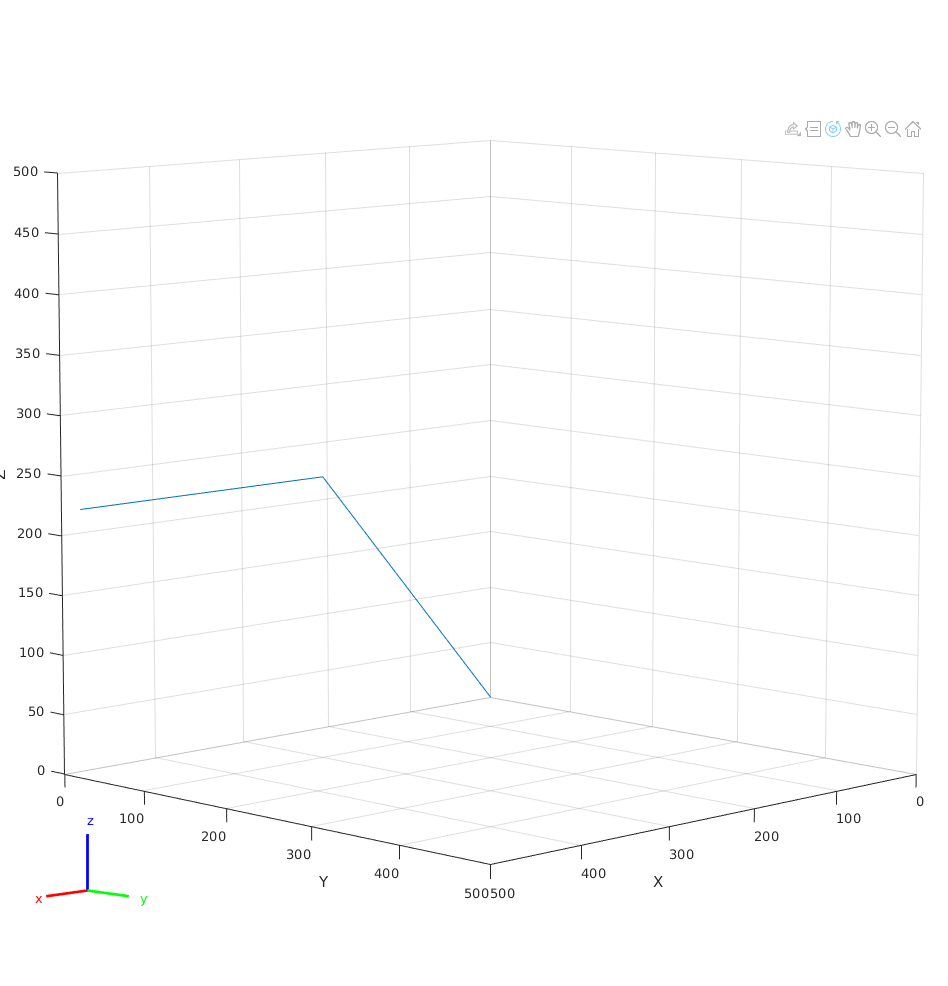

show(denso_robot);
axis([0,500,0,500,0,500])
axis on

### **Optional: Show different configuration**

As another optional section, here we edit the configuration of the robot to "move" it. First, we make a copy of the home configuration.

config = homeConfiguration(denso_robot);

Now, we can edit this configuration however we please. Let us set all the revolute joints to $\frac{\pi }{4}$, and the prismatic to -*100*.

config(1).JointPosition = pi/4;
config(2).JointPosition = pi/4;
config(3).JointPosition = -100;
config(4).JointPosition = pi/4;

Show configuration table.

config

config = 1×4 struct array with fields:
    JointName
    JointPosition


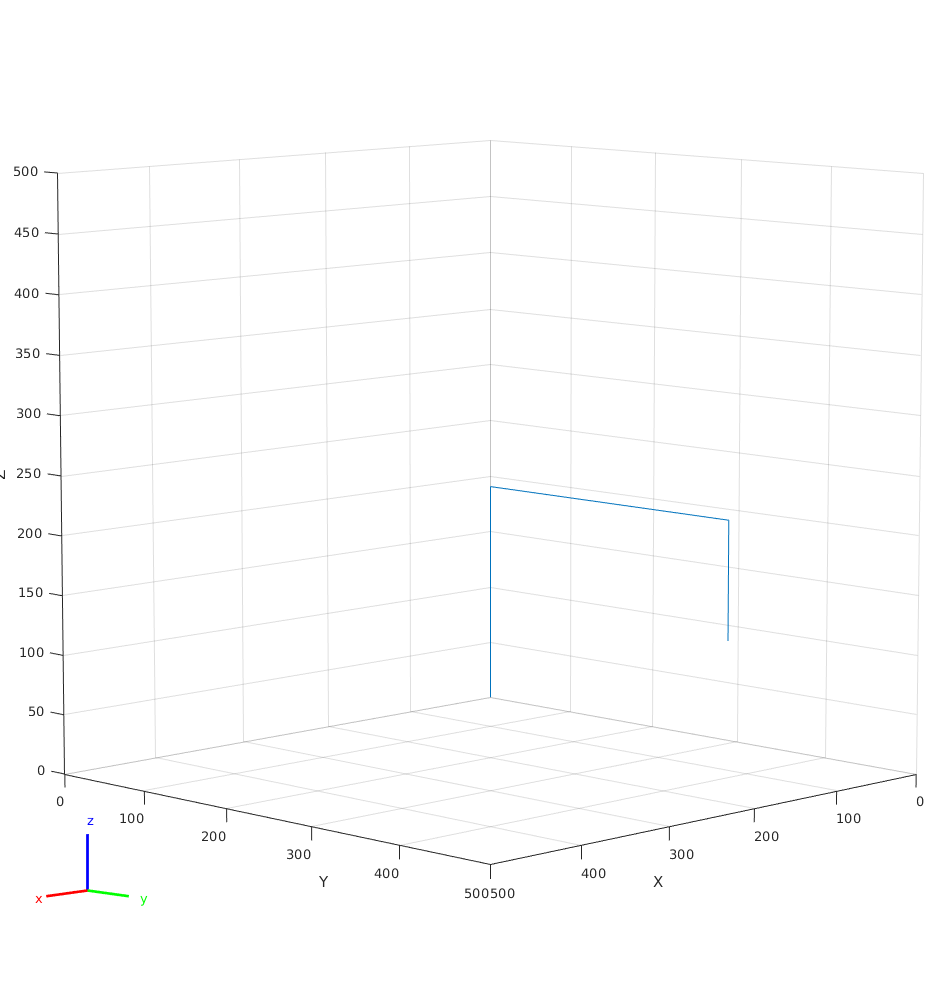

ax = show(denso_robot, config);
axis([0,500,0,500,0,500])
axis on

## *Show end-effector trajectory for given inputs*

We will now obtain the end-effector trajectory for varying inputs of $\theta_1$ and $\theta_2$.

First, we define a time array to simulate a 10 second timing. Our step size is 10 ms.

time_step = 0.01;
time_arr = 0:time_step:10;
[~,time_arr_len] = size(time_arr);

Now, we loop through each value in the time array and compute the transformation (the supporting function computeTransform calls the required getTransform() function).

trans_arr = zeros(4,4,time_arr_len);
i = 1;
for t = time_arr
    transformation = computeTransform(denso_robot, t);
    trans_arr(:,:,i) = transformation;
    i = i + 1;
end

Now, we can extract the trail of x,y,z catesian coordinates of the end-effector trajectory. We can ignore the rotation matrix because it does not matter for showing the trajectory of the tool frame.

end_eff_traj = trans_arr(1:3,4,:);

Next, we flatten the coordinate arrays for each axis into their own 2D arrays.

x_arr = reshape(end_eff_traj(1,1,:),[1,time_arr_len]);
y_arr = reshape(end_eff_traj(2,1,:),[1,time_arr_len]);
z_arr = reshape(end_eff_traj(3,1,:),[1,time_arr_len]);

### Translational solution I: plot 3D trajectory with time annotations

Now we plot the translational trajectory in 3D space, with annotations showing the time points for the period of 1 second. The trajectory repeats for each second. Rotations are not shown in this plot.

plot3(x_arr,y_arr,z_arr)
title("3D trajectory with time annotations (1 sec)");
xlabel("x axis")
ylabel("y axis")
zlabel("z axis")
i = 1

i = 1

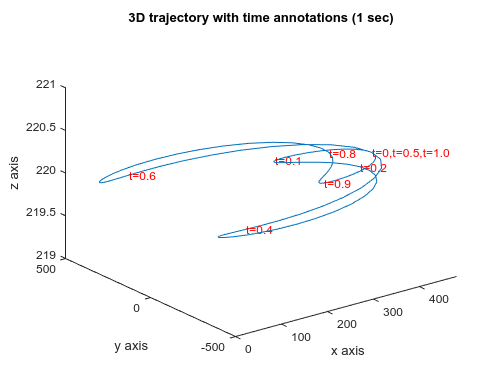

for t = time_arr
    if (ismember(t,0.1:0.1:0.4) || ismember(t,0.6:0.1:0.9))
        str = sprintf('t=%0.1f',t);
        text(x_arr(i),y_arr(i),z_arr(i),str,"Color","r");
    elseif (t==0.5)
        text(x_arr(i),y_arr(i),z_arr(i),"t=0,t=0.5,t=1.0","Color","r");
    end
    i = i + 1;
end

### Translational solution II: plot XY trajectory against time

Since the end-effector's Z coordinate stays at a constant *220* during the entire trajectory, we can also ignore the Z axis and plot the XY trajectory against time, as another 3D plot. Rotations are not shown in this plot.

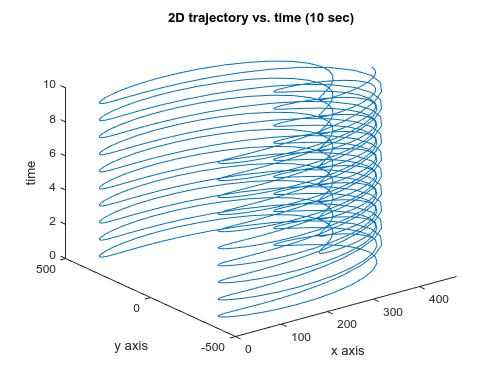

plot3(x_arr,y_arr,time_arr)
title("2D trajectory vs. time (10 sec)")
xlabel("x axis")
ylabel("y axis")
zlabel("time")

### Rotational solution: plot Euler angles variation against time

We can use the *3x3 *rotation matrices in our transformations array to convert to Euler angles (ZYX sequence).

i = 1;
euler_z = zeros(1,time_arr_len);
euler_y = zeros(1,time_arr_len);
euler_x = zeros(1,time_arr_len);
for t = time_arr
    euler_zyx = tform2eul(trans_arr(:,:,i));
    euler_z(i) = euler_zyx(:,1);
    euler_y(i) = euler_zyx(:,2);
    euler_x(i) = euler_zyx(:,3);
    i = i+1;
end

Next, we can plot the Euler angles.

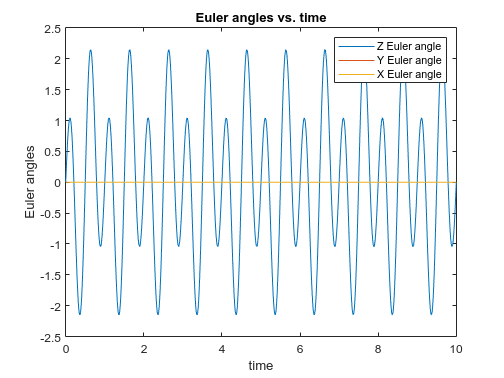

plot(time_arr,euler_z)
hold on
plot(time_arr,euler_y)
hold on
plot(time_arr,euler_x)
title("Euler angles vs. time");
xlabel("time");
ylabel("Euler angles");
legend("Z Euler angle", "Y Euler angle", "X Euler angle");
hold off

In the plot, we see that only the Z Euler Angle varies, and the Y and X angles stay at 0.

### Integrated solution (translations & rotations)

***Warning: This section uses quite a bit of computing power and can take a while to run.***

We can also plot the entire transformation matrix using plotTransform(). First we form the translations and rotations.

translations = zeros(time_arr_len,3);
rotations = zeros(time_arr_len, 4);
i = 1;
for t = time_arr
    translations(i,:) = end_eff_traj(1:3,1,i)';
    rotations(i,:) = rotm2quat(trans_arr(1:3,1:3,i));
    i = i+1;
end

Now we can plot the tranforms.

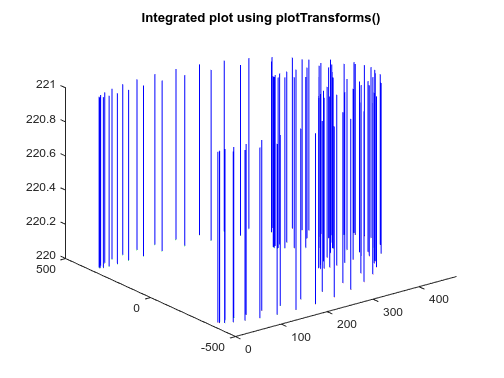

plotTransforms(translations, rotations)
title("Integrated plot using plotTransforms()")

**Supporting functions**

The following function edits the configuration of the Denso HSR robot for a given time t, and returns the transformation.

function T = computeTransform(robot, time_point)
    % Compute theta1 and theta2
    theta1 = (-pi/4)*sin(2*pi*time_point);
    theta2 = (pi/2)*sin(4*pi*time_point);
    % Edit configuration
    config = homeConfiguration(robot);
    config(1).JointPosition = theta1;
    config(2).JointPosition = theta2;
    % Get the transformation for the edited configuration
    T = getTransform(robot, config, 'body4','base');
end